# Introduction to regression

In microbiome timeseries datasets, there may be tens, hundreds, or even thousands of distinct populations. We can use regression to estimate relationships among variables.

In this tutorial, we demonstrate how to perform linear regression as well as linear regression with regularization. We also demonstrate a heuristic for identifying if a problem is underdetermined.

## Simple linear regression

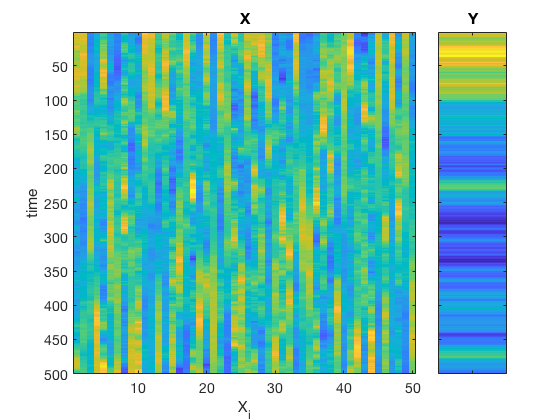

clear;

N = 50; % number of variables
NT = 500; % number of timepoints

% 'timeseries' data, independent variables
X = normrnd(0,1,[NT N]);
X = cumsum(X);
X = (X-mean(X))./std(X); % z-score

% true regression coefficients
beta_true = rand(N+1,1);

% the dependent variable
Y = [ones(NT,1) X]*beta_true;

figure();
subplot(1,5,[1 4]);
imagesc(X);
ylabel('time');
xlabel('X_i');
title('X');
set(gca,'FontSize',14);
subplot(1,5,5);
imagesc(Y);
title('Y');
set(gca,'FontSize',14,'XTickLabel',[],'YTickLabel',[]);

The goal is to predict to what extent each X_i contributes to the observed Y.

X0 = [ones(NT,1) X]; % include a constant term
beta = pinv(X0)*Y;

mse = mean((Y-X0*beta).^2);
disp(mse);

   9.0270e-29



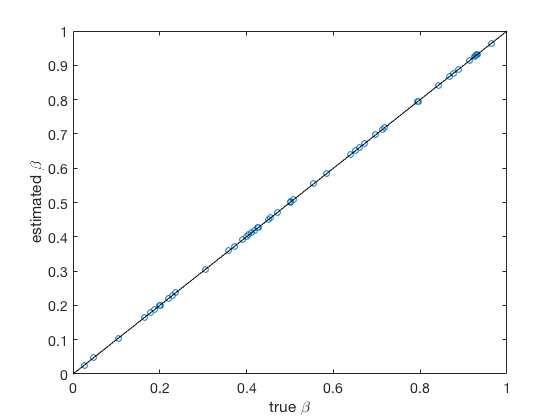


figure();
plot(beta_true,beta,'o');
plot_one2one();
xlabel('true \beta');
ylabel('estimated \beta');
set(gca,'FontSize',14);

How does measurement noise affect the accuracy of our result?

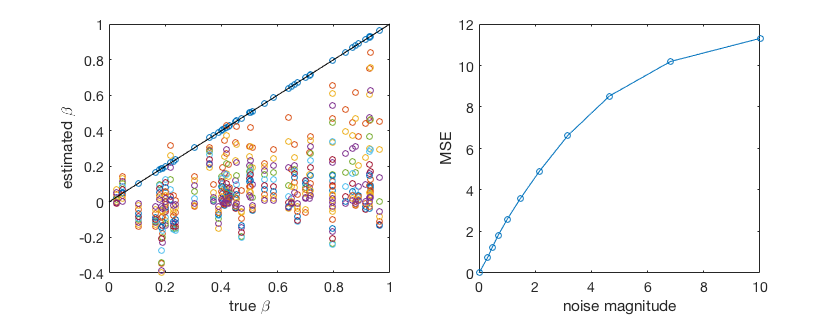

sigma = [0 logspace(-0.5,1,10)];
epsilon = normrnd(0,1,[NT N]); % assume normally distributed, independent errors
mse = zeros(length(sigma),1);

figure();
subplot(1,2,1);
hold on;

for i = 1:length(sigma)
    Xnoisy = X + sigma(i)*epsilon;
    X0 = [ones(NT,1) Xnoisy];
    beta = pinv(X0)*Y;
    mse(i) = mean((Y-X0*beta).^2);
    
    plot(beta_true,beta,'o');
end
plot_one2one();
xlabel('true \beta');
ylabel('estimated \beta');
set(gca,'FontSize',14,'Box','on');
subplot(1,2,2);
plot(sigma,mse,'o-');
xlabel('noise magnitude');
ylabel('MSE');
set(gca,'FontSize',14);
resize_figure(1,2);

## Linear regression with L1 regularization

If the $\beta$ are known to be sparse, we can add L1 regularization to the problem. L1 regularization penalizes non-zero entries in $\beta$, therefore selecting a few important variables and disregarding the rest. Regression with L1 regularization may perform better than simple regression when the number of variables is on par with the number of sampled timepoints, 

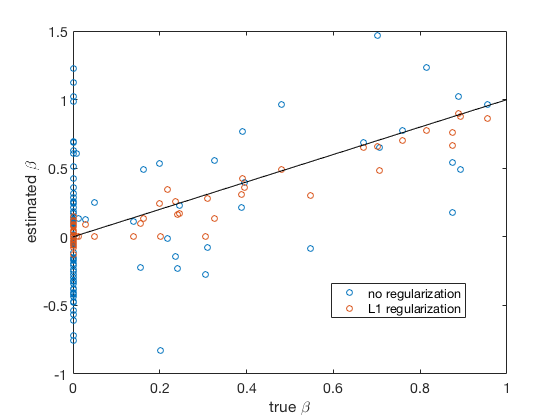

clear;

N = 100; % number of variables
NT = 100; % number of timepoints

% 'timeseries' data, independent variables
X = normrnd(0,1,[NT N]);
X = cumsum(X);
X = (X-mean(X))./std(X); % z-score

% true regression coefficients
beta_true = rand(N+1,1);
beta_true(randperm(N+1,round(0.7*N))) = 0;

% the dependent variable
noise = 0.3*(2*rand(NT,1)-1);
Y = [ones(NT,1) X]*beta_true + noise;

% simple linear regression
X0 = [ones(NT,1) X];
beta = pinv(X0)*Y;

% linear regression with regularization
[beta_lasso, stat] = lasso(X,Y);
beta_lasso = [stat.Intercept(1); beta_lasso(:,1)];

figure();
plot(beta_true,beta,'o');
hold on;
plot(beta_true,beta_lasso,'o');
hold off;
plot_one2one();
xlabel('true \beta');
ylabel('estimated \beta');
legend({'no regularization','L1 regularization'},'Location','best');
set(gca,'FontSize',14);

## Underdetermined problems

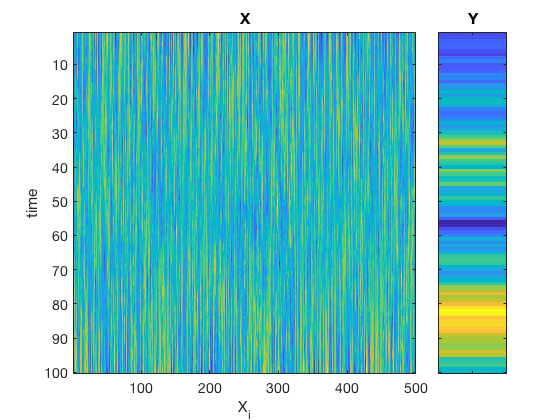

clear;

N = 500; % number of variables
NT = 100; % number of timepoints

% 'timeseries' data, independent variables
X = normrnd(0,1,[NT N]);
X = cumsum(X);
X = (X-mean(X))./std(X); % z-score

% true regression coefficients
beta_true = rand(N+1,1);

% the dependent variable
Y = [ones(NT,1) X]*beta_true;

figure();
subplot(1,5,[1 4]);
imagesc(X);
ylabel('time');
xlabel('X_i');
title('X');
set(gca,'FontSize',14);
subplot(1,5,5);
imagesc(Y);
title('Y');
set(gca,'FontSize',14,'XTickLabel',[],'YTickLabel',[]);

Simple linear regression does not perform well because there are too many variables and not enough sampled time points, i.e. the problem is *underdetermined*.

X0 = [ones(NT,1) X]; % include a constant term
beta = pinv(X0)*Y;

mse = 1/NT*sum((Y-X0*beta).^2);
disp(mse);

   3.6630e-27



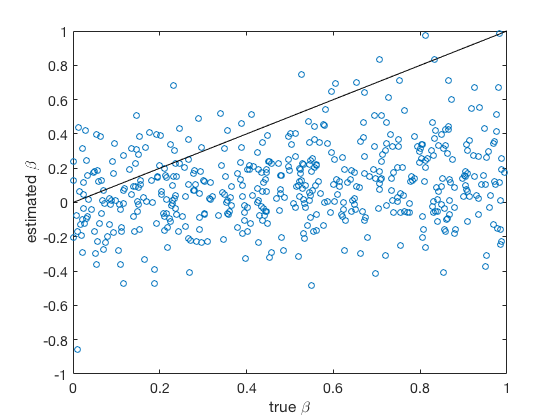

figure();
plot(beta_true,beta,'o');
plot_one2one();
xlabel('true \beta');
ylabel('estimated \beta');
set(gca,'FontSize',14);

How do we know if the problem is underdetermined without knowing the true $\beta$ ahead of time?

Ntrain = 0.8*NT; % split into training and testing sets
Xtrain = X(1:Ntrain,:);
Xtest = X(Ntrain+1:end,:);
X0train = [ones(Ntrain,1) Xtrain];
X0test = [ones(NT-Ntrain,1) Xtest];
Ytrain = Y(1:Ntrain);
Ytest = Y(Ntrain+1:end);

beta_train = pinv(X0train)*Ytrain; % compute beta on the training set

mse_train = 1/NT*sum((Ytrain-X0train*beta_train).^2);
mse_test = 1/NT*sum((Ytest-X0test*beta_train).^2);
disp(mse_train); % small training error -> good fit to training data

   1.0210e-28



disp(mse_test); % large testing error -> overfit to training data, low predictive power

    3.4433



The testing to training error ratio can be used as a heuristic for identifying if a problem is underdetermined. If testing error is much larger than the training error (i.e. by orders of magnitude), the problem is underdetermined.